# Aula 4 - Laboratório de Controle - 2022/1

## **Resposta no tempo de sistemas de primeira e segunda ordem: regime e transitório**

## Nome:

Ler o  [material complementar da aula 4 ](https://classroom.google.com/c/NTE0NDk4OTQ4Mjgw/m/NTMxODU3Mzg0MTUz/details)antes de começar. 

**Inicialização: (Não alterar as 5 linhas de código abaixo)**

Turma=0;
I=0;
g2=init(Turma,I)
b0=g2.Numerator{1}(3);p0=g2.Denominator{1}(3);
datetime('now')
pwd
tic

## Atividade 1 - Constante de tempo de sistema de primeira ordem

1.1 Analise a resposta ao degrau unitário de $g_2(s)$, e ao aproximar sua resposta pela de um sistema de ordem 1 $g_1(s)$, obtenha sua constante de tempo T. Use a figura 4.2 de [Livro](https://classroom.google.com/c/NTE0NDk4OTQ4Mjgw/m/NTMxODU3Mzg0NTYy/details)  como referência.

figure; 
step(g2);title('Figura 1: Resposta ao degrau de g_2')


Obtenha a constante de tempo considerando a saída em 63% do valor de regime, informando o svalores utilizados no cálculo.

1.2 Quantas constantes de tempo são necessárias para que a saída do sistema se aproxime do valor de regime? (99%)

1.3 Obtenha o ganho de $g_1(s)$, isto é, a FT $g_2(s)$ aproximada por uma de ordem 1, analisando seu valor em regime (ver novamente a figura 4.2, na qual a FT é simulada para ganho unitário). $g_1(s)=\frac{K}{Ts+1}$ como sendo a FT de ordem 1 com o ganho K e a constante de tempo T, simule ao degrau $g_2(s)$ e $g_1(s)$, comparando suas respostas. 

figure;
g1=tf(K,[T 1]);  % Substitua os valores de T e K obtidos
step(g1,g2);title('Figura 2. Comparação de g_1 e g_2');

Comente a semelhança entre as respostas e as partes das curvas que mais se aproximam:

## Atividade 2 - Análise do erro em regime

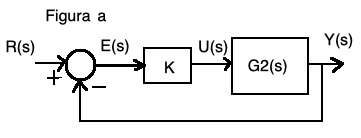

Abaixo são usados 20 valores de ganho $K$ para fechar a malha e calcular o [erro em regime. ](http://www.fem.unicamp.br/~em621/aulas/aula16/analiserro.pdf)$E(s)=\frac{R(s)}{1+KG_{2}(s)}$ para uma entrada degrau unitário $R(s)$, conforme a Figura a. 

k=linspace(p0/(0.25*b0)-1/b0,p0/(0.01*b0)-1/b0,20);
for i=1:length(k)
    m=feedback(1,k(i)*g2);
    erro(i)=freqresp(m,0);% Teorema do valor final sobre E(s)
end
plot(k,erro);title('Figura 3. - Erro em função do ganho ');
tt1=toc;
xlabel('Ganho k');ylabel('Erro');

2.1 Qual o efeito do ganho no erro em regime? 

2.2 Para que valores de ganho K o erro é menor que 5%? 

2.3 Qual o erro em regime para sistemas com tipo ([erro em regime ](http://www.fem.unicamp.br/~em621/aulas/aula16/analiserro.pdf)) igual ao de g2?

Na figura 4 é mostrada a resposta Y(s) ao degrau unitário R(s) bem como o erro E(s) e a integral absoluta do erro (IAE), calculada por $iae=\int_{0}^{3}|e(t)|dt$. Observe que o iae é integrado para cada tempo t. O valor utilizado para comparações é aquele obtido na janela de tempo total, ou seja, em t=3, neste caso igual a 1.25.

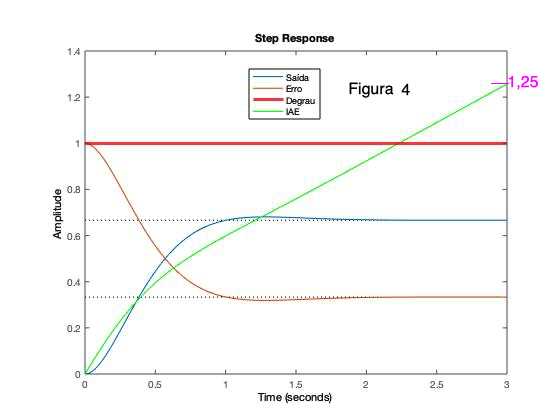

2.4 Para que valor tende o IAE e por quê?

2.5 Qual o efeito do tempo de estabelecimento sobre o IAE?

## Atividade 3 - Erro em regime e resposta transitória

m1=feedback(k(1)*g2,1);
m2=feedback(k(end)*g2,1);
step(m1,m2);
title('Figura 4. - Resposta ao degrau unitário para dois ganhos');

3.1 Na figura 4 é mostrada a resposta ao degrau unitário para o menor e maior ganhos usados na figura 2. Compare o efeito do ganho K na resposta ao degrau unitário em regime e no período transitório, informando os ganhos usados  (ver figura 3).

A sobreelevação se relaciona com o amortecimento $\zeta$ pela equação $UP=100 e^-({\frac{\zeta \pi}{\sqrt{1-\zeta^2}}})$. O script abaixo calcula os valores de UP para um conjunto de valores de $\zeta$.

zeta=linspace(0.01,0.95,20);
for i=1:20
UP(i)=100*exp(-zeta(i)*pi/(sqrt(1-zeta(i)^2)));
end
plot(zeta,UP);title('Figura 5. - Sobreelevação UP e amortecimento \zeta ');
xlabel('\zeta');ylabel('UP')


3.2 Explique a relação entre UP e $\zeta$ usando a figura 5 gerada pelo script.

3.3 Use a figura 5 para obter os valores de $\zeta$para os quais se tem $UP\leq 5\%$?

## Atividade 4 - Análise da resposta transitória

Use o comando rlocus(g2) ou rlocus(g2,k) para obter k1 de modo a ter $\zeta=0.7$ e k2 de modo a ter $\zeta=0.3$, e substitua estes valores abaixo e execute o script. 

## Importante: mostre a figura gerada pelo script abaixo ao professor antes de responder as 4 perguntas desta atividade.

k=linspace(k1,k2,20); % Substitua aqui os valoes de k1 e k2
for i=1:20
    m=feedback(k(i)*g2,1);
    s=stepinfo(m);
    U(i,:)=[s.RiseTime s.SettlingTime s.Overshoot];
    if i==1 
        [y,t]=step(m);Tempo=max(t);
    else
        [y,t]=step(m,Tempo);
    end
    IAE(i)=trapz(t,abs(1-y));
end

subplot(4,1,1);bar(k,(U(:,1)));title('Figura 6. Tempo de subida (t_r) ');
subplot(4,1,2);bar(k,(U(:,2)));title('Tempo de estabelecimento (t_s)');
subplot(4,1,3);bar(k,(U(:,3)));title('Sobreelevação (UP)');
subplot(4,1,4);bar(k,(IAE));title('IAE');
tt2=toc/tt1

4.1 Qual o efeito do ganho K no tempo de subida ($t_r$)?

4.2 Qual o efeito do ganho K na sobreelevação (UP)?

4.3 Explique o comportamento do tempo de estabelecimento ($t_s$) quando o ganho K varia.

4.4 Quem afeta mais o valor de IAE? UP, $t_r$ ou $t_s$?

4.5 Use a equação 4.31 ou 4.32  de [livro](https://classroom.google.com/c/NTE0NDk4OTQ4Mjgw/m/NTMxODU3Mzg0NTYy/details) para explicar a relação entre o tempo de estabelecimento e a parte real dos polos para sistemas de ordem 2 com polos complexos. Aplique a equação para algum valor de K da figura 6, mostrando a relação.

## IMPORTANTE:Executar todo o live script com RUN para gerar o relatório a ser entregue.